# Robotic Identification of Kinesthetic deficits after stroke - Semrau et al., 2013

Created June 1, 2021

clear; clc;
cd('/Users/duncan/OneDrive - University of Delaware - o365/Documents/Presentations/Semrau_2013')

## Targets

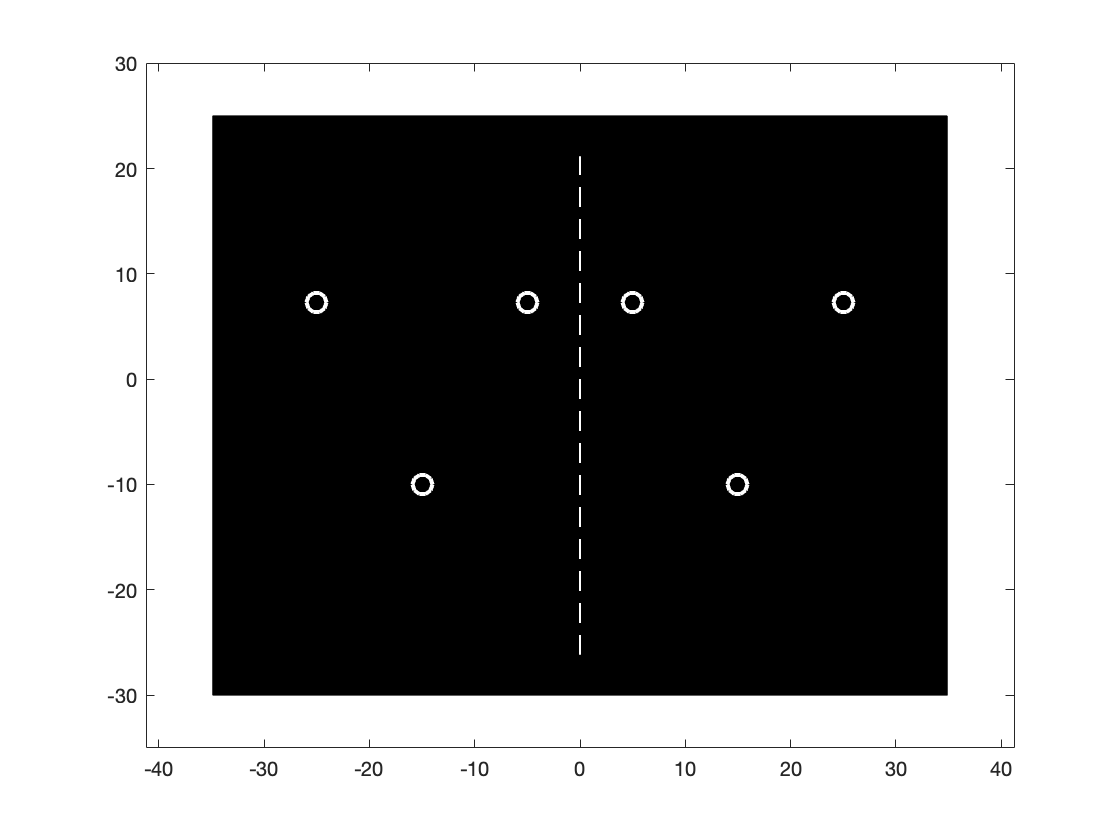

% trig
home = [-10,-10]; 
dists = 20; 
theta = acosd((dists^2 + dists^2 - dists^2) / (2 * dists * dists)); 
left = [dists * cosd(120) + home(1), dists * sind(120) + home(2)];
right = [dists * cosd(60) + home(1), dists * sind(120) + home(2)]; 

% combine 
ATBA_targs = [home; left; right]; 
% displace 
ATBA_targs(:,1) = ATBA_targs(:,1) - 5; 
% mirror
nATBA_targs = [-ATBA_targs(:,1), ATBA_targs(:,2)]; 

% visual confirmation 
figure();
plot(ATBA_targs(:,1), ATBA_targs(:,2), 'o', 'markersize', 10, 'color', 'w', 'linewidth', 2)
hold on 
plot(nATBA_targs(:,1), nATBA_targs(:,2), 'o', 'markersize', 10, 'color', 'w', 'linewidth', 2)
axis equal 
axis padded 
vline(0, 'w', '--', 1);
kBackground(gca); 

rotation_matrix = [nan, 120, 60; 300, nan, 0; 240, 180, nan]; 

## Movements

robot_peak = 0.28; 
duration = round(s_to_ms(dur_calc_KINARM(ATBA_targs(1,:), ATBA_targs(2,:), robot_peak)));
time = 1:1:duration; 
[reachX, reachY] = T1reachT2(ATBA_targs(1,:), ATBA_targs(2,:), duration); 
robot_vel = reachXY2vel(reachX, reachY, time);

## Simulate 1 trial 

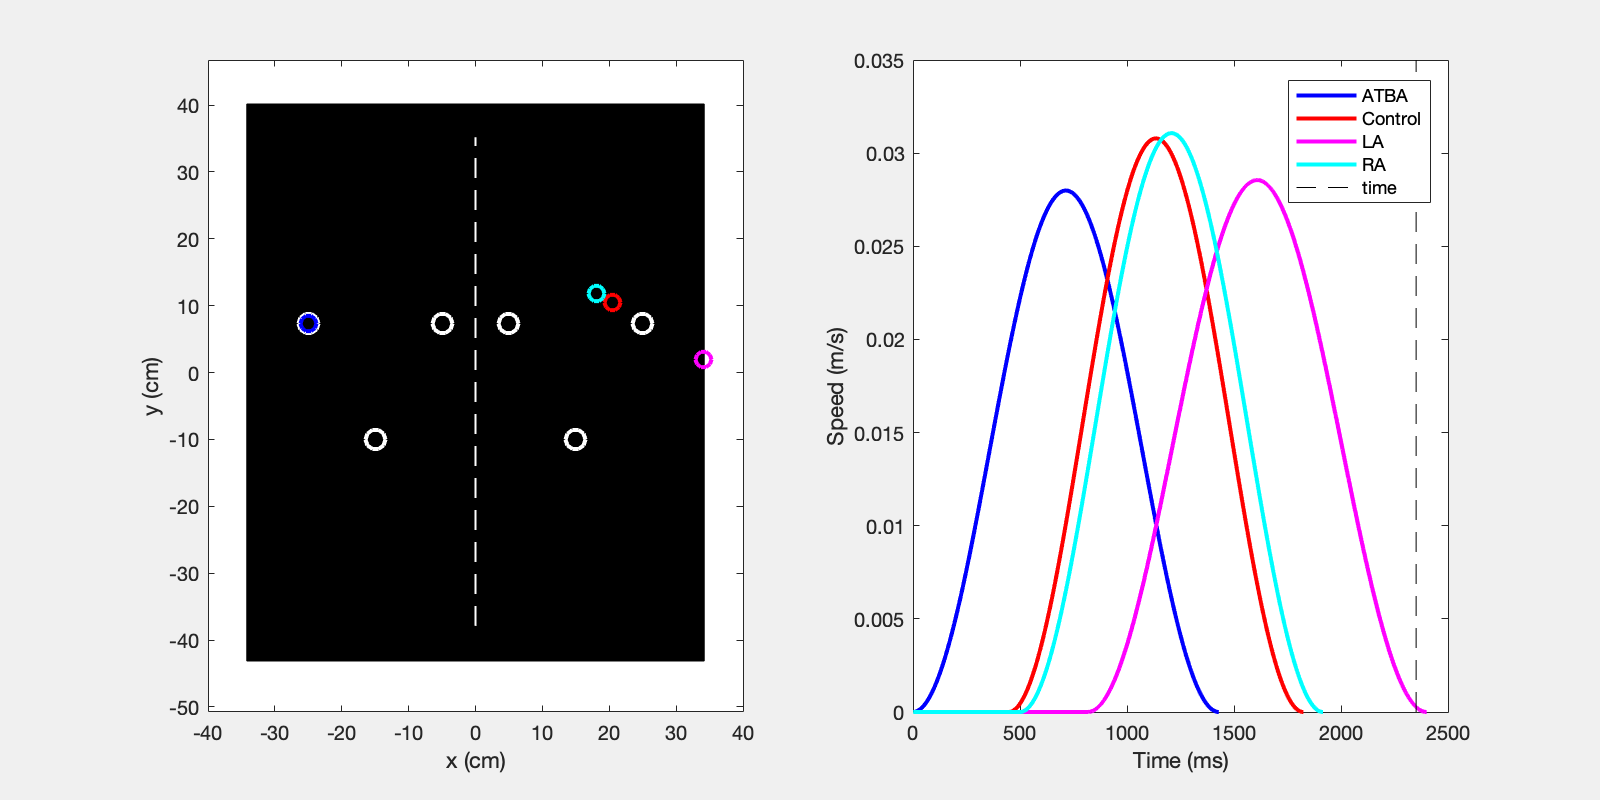

% Set up reaches (spatially and temporally) 

% Parameters 
% RL
RL_C = 893 / 2;
RL_LA = 817; 
RL_RA = 500; 
% PSR
PSR_C = (0.8 + 1.4) / 2; 
PSR_LA = 1.02; 
PSR_RA = 1.11; 
% IDE 
IDE_C = 14.8; 
IDE_LA = 28; 
IDE_RA = 22.1; 
% PLR
PLR_C = 1.06; 
PLR_LA = 1.13; 
PLR_RA = 1.10; 

% robot 
[robX, robY, time] = reach_wKIN(ATBA_targs(1,:), ATBA_targs(2,:), robot_peak, [], [], [], [], [], []);
robot_vel = reachXY2vel(robX, robY, time);

% control
[controlX, controlY, time] = reach_wKIN(ATBA_targs(1,:), ATBA_targs(2,:), robot_peak, RL_C, PSR_C, PLR_C, IDE_C, rotation_matrix, [1 2]); 
control_vel = reachXY2vel(controlX, controlY, time); 

% LA
[LAX, LAY, time] = reach_wKIN(ATBA_targs(1,:), ATBA_targs(2,:), robot_peak, RL_LA, PSR_LA, PLR_LA, IDE_LA, rotation_matrix, [1 2]); 
LA_vel = reachXY2vel(LAX, LAY, time); 

% RA
[RAX, RAY, time] = reach_wKIN(ATBA_targs(1,:), ATBA_targs(2,:), robot_peak, RL_RA, PSR_RA, PLR_RA, IDE_RA, rotation_matrix, [1 2]); 
RA_vel = reachXY2vel(RAX, RAY, time); 

% Set up plotting
robot_color = 'b'; 
control_color = 'r'; 
LA_color = 'm';
RA_color = 'c'; 

% visualize 
figure("Position",[300, 300 800 400], 'visible', 'on');

% control 
subplot(1,2,1); % position 
plot(ATBA_targs(:,1), ATBA_targs(:,2), 'o', 'markersize', 10, 'color', 'w', 'linewidth', 2) % ATBA targets 
hold on 
plot(nATBA_targs(:,1), nATBA_targs(:,2), 'o', 'markersize', 10, 'color', 'w', 'linewidth', 2) % nATBA targets
plot(nan, nan, 'bo', 'linewidth', 2, 'markersize', 8); % ATBA hand 
% nATBA hand 
plot(nan, nan, 'o', 'LineWidth', 2, 'markersize', 8, 'color', control_color); % control 
plot(nan, nan, 'o', 'LineWidth', 2, 'markersize', 8, 'color', LA_color); % LA 
plot(nan, nan, 'o', 'LineWidth', 2, 'markersize', 8, 'color', RA_color); % RA 
axis equal 
axis padded 
vline(0, 'w', '--', 1);
kBackground(gca); 
xlabel('x (cm)'); ylabel('y (cm)'); 
posG_C = gca(); 

subplot(1,2,2); % velocity
plot(1:length(robot_vel), robot_vel, 'b-', 'linewidth', 2, 'displayname', 'ATBA'); % ATBA velocity 
hold on 
% nATBA velocity
plot(1:length(control_vel), control_vel, '-', 'linewidth', 2, 'color', control_color, 'displayname', 'Control'); % control
plot(1:length(LA_vel), LA_vel, '-', 'linewidth', 2, 'color', LA_color, 'displayname', 'LA'); % LA
plot(1:length(RA_vel), RA_vel, '-', 'linewidth', 2, 'color', RA_color, 'displayname', 'RA'); % RA
plot([nan nan], [nan nan], 'k--', 'displayname', 'time'); % time line
xlabel('Time (ms)'); ylabel('Speed (m/s)')
legend('location', 'best')
velG_C = gca(); 

max_time = max([length(robot_vel), length(control_vel), length(LA_vel), length(RA_vel)]); 
% visualize 
for i = 1:50:max_time
    
    subplot(1,2,1);
    % ATBA hand (5)
    if i <= length(robX)
        set(posG_C.Children(5), 'XData', robX(i));
        set(posG_C.Children(5), 'YData', robY(i)); 
    end
    % nATBA hand 
    % control (4)
    if i <= length(controlX)
        set(posG_C.Children(4), 'XData', -controlX(i));
        set(posG_C.Children(4), 'YData', controlY(i)); 
    end
    % LA (3)
    if i <= length(LAX)
        set(posG_C.Children(3), 'XData', -LAX(i));
        set(posG_C.Children(3), 'YData', LAY(i)); 
    end
    % RA (2)
    if i <= length(RAX)
        set(posG_C.Children(2), 'XData', -RAX(i));
        set(posG_C.Children(2), 'YData', RAY(i)); 
    end
    
    % time slider 
    subplot(1,2,2);
    set(velG_C.Children(1), 'XData', [i, i]); 
    set(velG_C.Children(1), 'YData', velG_C.YLim);
    
    pause(ms_to_s(1)); 
end

## Simulate multiple trials

% Set up
schedule = [1 2 3 2 1]; 
robotXTotal = [];
robotYTotal = []; 
robotVelTotal = []; 
controlXTotal = [];
controlYTotal = []; 
controlVelTotal = []; 
LAXTotal = [];
LAYTotal = []; 
LAVelTotal = []; 
RAXTotal = [];
RAYTotal = []; 
RAVelTotal = []; 

for i = 1:length(schedule)-1
    
    % where from , where to 
    start_targ_idx = schedule(i);
    end_targ_idx = schedule(i+1);
    
    % robot 
    [robX, robY, time] = reach_wKIN(ATBA_targs(start_targ_idx,:), ATBA_targs(end_targ_idx,:), robot_peak, [], [], [], [], [], []);
    rob_vel = reachXY2vel(robX, robY, time);
    
    % control
    [controlX, controlY, time] = reach_wKIN(ATBA_targs(start_targ_idx,:), ATBA_targs(end_targ_idx,:), robot_peak, RL_C, PSR_C, PLR_C, IDE_C, ...
        rotation_matrix, [start_targ_idx end_targ_idx]); 
    control_vel = reachXY2vel(controlX, controlY, time); 
    
    % LA
    [LAX, LAY, time] = reach_wKIN(ATBA_targs(start_targ_idx,:), ATBA_targs(end_targ_idx,:), robot_peak, RL_LA, PSR_LA, PLR_LA, IDE_LA, ...
        rotation_matrix, [start_targ_idx end_targ_idx]); 
    LA_vel = reachXY2vel(LAX, LAY, time); 
    
    % RA
    [RAX, RAY, time] = reach_wKIN(ATBA_targs(start_targ_idx,:), ATBA_targs(end_targ_idx,:), robot_peak, RL_RA, PSR_RA, PLR_RA, IDE_RA, ...
        rotation_matrix, [start_targ_idx end_targ_idx]); 
    RA_vel = reachXY2vel(RAX, RAY, time); 
    
    % robot bring back to position 
    % robot 
    robHomeX = ones([1 750]) * robX(end);
    robHomeY = ones([1 750]) * robY(end); 
    robHomeVel = zeros([1 750]); 
    % control
    [controlHomeX, controlHomeY] = T1reachT2([controlX(end), controlY(end)], ATBA_targs(end_targ_idx,:), 750); 
    controlHomeVel = reachXY2vel(controlHomeX, controlHomeY, 1:1:750); 
    % LA
    [LAHomeX, LAHomeY] = T1reachT2([LAX(end), LAY(end)], ATBA_targs(end_targ_idx,:), 750); 
    LAHomeVel = reachXY2vel(LAHomeX, LAHomeY, 1:1:750); 
    % RA
    [RAHomeX, RAHomeY] = T1reachT2([RAX(end), RAY(end)], ATBA_targs(end_targ_idx,:), 750); 
    RAHomeVel = reachXY2vel(RAHomeX, RAHomeY, 1:1:750); 
    
    % append 
    robotXTotal = [robotXTotal, robX, robHomeX];
    robotYTotal = [robotYTotal, robY, robHomeY]; 
    robotVelTotal = [robotVelTotal, rob_vel, robHomeVel]; 
    controlXTotal = [controlXTotal, controlX, controlHomeX];
    controlYTotal = [controlYTotal, controlY, controlHomeY]; 
    controlVelTotal = [controlVelTotal, control_vel, controlHomeVel]; 
    LAXTotal = [LAXTotal, LAX, LAHomeX];
    LAYTotal = [LAYTotal, LAY, LAHomeY]; 
    LAVelTotal = [LAVelTotal, LA_vel, LAHomeVel]; 
    RAXTotal = [RAXTotal, RAX, RAHomeX];
    RAYTotal = [RAYTotal, RAY, RAHomeY]; 
    RAVelTotal = [RAVelTotal, RA_vel, RAHomeVel];
    
    fprintf('iteration %d \n', i)
    
end

iteration 1 
iteration 2 
iteration 3 
iteration 4 


## Visualize multiple trials

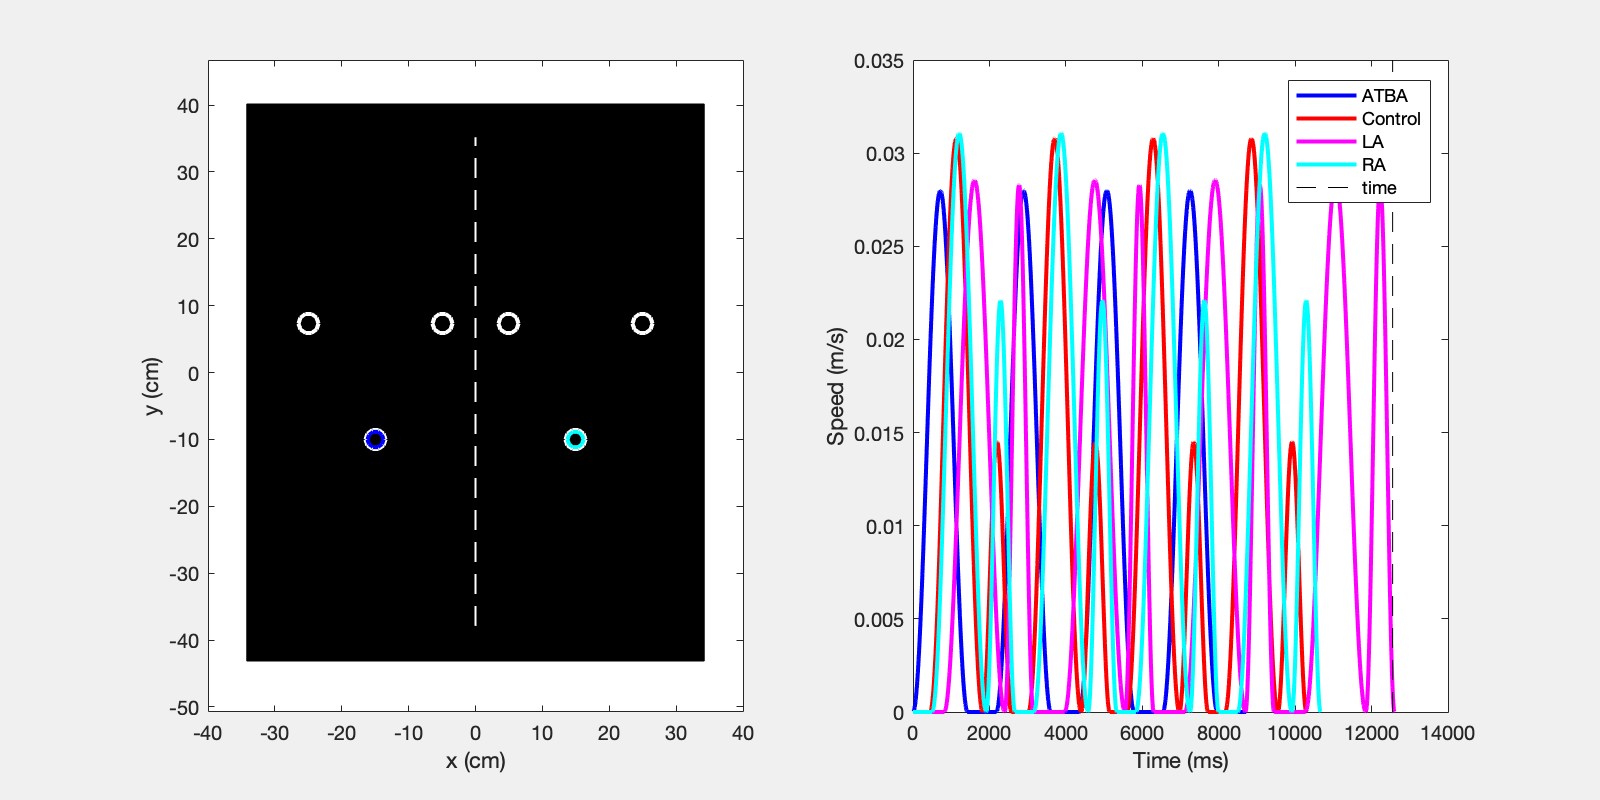

% visualize 
figure("Position",[300, 300 800 400], 'visible', 'on');

% control 
subplot(1,2,1); % position 
plot(ATBA_targs(:,1), ATBA_targs(:,2), 'o', 'markersize', 10, 'color', 'w', 'linewidth', 2) % ATBA targets 
hold on 
plot(nATBA_targs(:,1), nATBA_targs(:,2), 'o', 'markersize', 10, 'color', 'w', 'linewidth', 2) % nATBA targets
plot(nan, nan, 'bo', 'linewidth', 2, 'markersize', 8); % ATBA hand 
% nATBA hand 
plot(nan, nan, 'o', 'LineWidth', 2, 'markersize', 8, 'color', control_color); % control 
plot(nan, nan, 'o', 'LineWidth', 2, 'markersize', 8, 'color', LA_color); % LA 
plot(nan, nan, 'o', 'LineWidth', 2, 'markersize', 8, 'color', RA_color); % RA 
axis equal 
axis padded 
vline(0, 'w', '--', 1);
kBackground(gca); 
xlabel('x (cm)'); ylabel('y (cm)'); 
posG_C = gca(); 

subplot(1,2,2); % velocity
plot(1:length(robotVelTotal), robotVelTotal, 'b-', 'linewidth', 2, 'displayname', 'ATBA'); % ATBA velocity 
hold on 
% nATBA velocity
plot(1:length(controlVelTotal), controlVelTotal, '-', 'linewidth', 2, 'color', control_color, 'displayname', 'Control'); % control
plot(1:length(LAVelTotal), LAVelTotal, '-', 'linewidth', 2, 'color', LA_color, 'displayname', 'LA'); % LA
plot(1:length(RAVelTotal), RAVelTotal, '-', 'linewidth', 2, 'color', RA_color, 'displayname', 'RA'); % RA
plot([nan nan], [nan nan], 'k--', 'displayname', 'time'); % time line
xlabel('Time (ms)'); ylabel('Speed (m/s)')
legend('location', 'best')
velG_C = gca(); 

max_time = max([length(robotVelTotal), length(controlVelTotal), length(LAVelTotal), length(RAVelTotal)]); 
% visualize 
for i = 1:50:max_time
    
    subplot(1,2,1);
    % ATBA hand (5)
    if i <= length(robotXTotal)
        set(posG_C.Children(5), 'XData', robotXTotal(i));
        set(posG_C.Children(5), 'YData', robotYTotal(i)); 
    end
    % nATBA hand 
    % control (4)
    if i <= length(controlXTotal)
        set(posG_C.Children(4), 'XData', -controlXTotal(i));
        set(posG_C.Children(4), 'YData', controlYTotal(i)); 
    end
    % LA (3)
    if i <= length(LAXTotal)
        set(posG_C.Children(3), 'XData', -LAXTotal(i));
        set(posG_C.Children(3), 'YData', LAYTotal(i)); 
    end
    % RA (2)
    if i <= length(RAXTotal)
        set(posG_C.Children(2), 'XData', -RAXTotal(i));
        set(posG_C.Children(2), 'YData', RAYTotal(i)); 
    end
    
    % time slider 
    subplot(1,2,2);
    set(velG_C.Children(1), 'XData', [i, i]); 
    set(velG_C.Children(1), 'YData', velG_C.YLim);
    
    pause(ms_to_s(1)); 
end

## Multiple trials, one at a time

schedule = [1 2 1 3 1 3 2 3 2]; 
% Set up reaches (spatially and temporally) 
    
% Parameters 
% RL
RL_C = 893 / 2;
RL_LA = 817; 
RL_RA = 500; 
% PSR
PSR_C = (0.8 + 1.4) / 2; 
PSR_LA = 1.02; 
PSR_RA = 1.11; 
% IDE 
IDE_C = 14.8; 
IDE_LA = 28; 
IDE_RA = 22.1; 
% PLR
PLR_C = 1.06; 
PLR_LA = 1.13; 
PLR_RA = 1.10;

for i = 1:length(schedule)-1
    
    filename = sprintf('T%d_T%d_ex.gif', schedule(i), schedule(i+1)); 

    % robot 
    [robX, robY, time] = reach_wKIN(ATBA_targs(schedule(i),:), ATBA_targs(schedule(i+1),:), robot_peak, [], [], [], [], [], []);
    robot_vel = reachXY2vel(robX, robY, time);
    
    % control
    [controlX, controlY, time] = reach_wKIN(ATBA_targs(schedule(i),:), ATBA_targs(schedule(i+1),:), robot_peak, RL_C, PSR_C, PLR_C, IDE_C, ...
        rotation_matrix, [schedule(i) schedule(i+1)]); 
    control_vel = reachXY2vel(controlX, controlY, time); 
    
    % LA
    [LAX, LAY, time] = reach_wKIN(ATBA_targs(schedule(i),:), ATBA_targs(schedule(i+1),:), robot_peak, RL_LA, PSR_LA, PLR_LA, IDE_LA, ...
        rotation_matrix, [schedule(i) schedule(i+1)]); 
    LA_vel = reachXY2vel(LAX, LAY, time); 
    
    % RA
    [RAX, RAY, time] = reach_wKIN(ATBA_targs(schedule(i),:), ATBA_targs(schedule(i+1),:), robot_peak, RL_RA, PSR_RA, PLR_RA, IDE_RA, ...
        rotation_matrix, [schedule(i) schedule(i+1)]); 
    RA_vel = reachXY2vel(RAX, RAY, time); 
    
    % Set up plotting
    robot_color = 'b'; 
    control_color = 'r'; 
    LA_color = 'm';
    RA_color = 'c'; 
    
    % visualize 
    figure("Position",[300, 300 800 400], 'visible', 'on');
    
    % control 
    subplot(1,2,1); % position 
    plot(ATBA_targs(:,1), ATBA_targs(:,2), 'o', 'markersize', 10, 'color', 'w', 'linewidth', 2) % ATBA targets 
    hold on 
    plot(nATBA_targs(:,1), nATBA_targs(:,2), 'o', 'markersize', 10, 'color', 'w', 'linewidth', 2) % nATBA targets
    plot(nan, nan, 'bo', 'linewidth', 2, 'markersize', 8); % ATBA hand 
    % nATBA hand 
    plot(nan, nan, 'o', 'LineWidth', 2, 'markersize', 8, 'color', control_color); % control 
    plot(nan, nan, 'o', 'LineWidth', 2, 'markersize', 8, 'color', LA_color); % LA 
    plot(nan, nan, 'o', 'LineWidth', 2, 'markersize', 8, 'color', RA_color); % RA 
    axis equal 
    axis padded 
    vline(0, 'w', '--', 1);
    kBackground(gca); 
    xlabel('x (cm)'); ylabel('y (cm)'); 
    posG_C = gca(); 
    
    subplot(1,2,2); % velocity
    plot(1:length(robot_vel), robot_vel, 'b-', 'linewidth', 2, 'displayname', 'ATBA'); % ATBA velocity 
    hold on 
    % nATBA velocity
    plot(1:length(control_vel), control_vel, '-', 'linewidth', 2, 'color', control_color, 'displayname', 'Control'); % control
    plot(1:length(LA_vel), LA_vel, '-', 'linewidth', 2, 'color', LA_color, 'displayname', 'LA'); % LA
    plot(1:length(RA_vel), RA_vel, '-', 'linewidth', 2, 'color', RA_color, 'displayname', 'RA'); % RA
    plot([nan nan], [nan nan], 'k--', 'displayname', 'time'); % time line
    xlabel('Time (ms)'); ylabel('Speed (m/s)')
    legend('location', 'best')
    velG_C = gca(); 
    
    max_time = max([length(robot_vel), length(control_vel), length(LA_vel), length(RA_vel)]); 
    % visualize 
    for i = 1:50:max_time
        
        subplot(1,2,1);
        % ATBA hand (5)
        if i <= length(robX)
            set(posG_C.Children(5), 'XData', robX(i));
            set(posG_C.Children(5), 'YData', robY(i)); 
        end
        % nATBA hand 
        % control (4)
        if i <= length(controlX)
            set(posG_C.Children(4), 'XData', -controlX(i));
            set(posG_C.Children(4), 'YData', controlY(i)); 
        end
        % LA (3)
        if i <= length(LAX)
            set(posG_C.Children(3), 'XData', -LAX(i));
            set(posG_C.Children(3), 'YData', LAY(i)); 
        end
        % RA (2)
        if i <= length(RAX)
            set(posG_C.Children(2), 'XData', -RAX(i));
            set(posG_C.Children(2), 'YData', RAY(i)); 
        end
        
        % time slider 
        subplot(1,2,2);
        set(velG_C.Children(1), 'XData', [i, i]); 
        set(velG_C.Children(1), 'YData', velG_C.YLim);
        
        writeGif(filename, i, 0.001)
        
%         pause(ms_to_s(1)); 
    end
    close(gcf);
end

function hand_vel = reachXY2vel(reachX, reachY, time)
XVel = derivative(reachX) ./ derivative(time); 
YVel = derivative(reachY) ./ derivative(time); 
hand_vel = sqrt(XVel.^2 + YVel.^2); 
end